### Load in Data

data = load("data/2017-12-05_Lederberg.mat")

data = struct with fields:
    spike_counts: [250×340×698 int8]
     brain_areas: [698×1 string]
           trial: [340×1 int32]
            cell: [698×1 int32]
            time: [250×1 double]


spike_counts = data.spike_counts;
brain_areas = data.brain_areas;
trials = data.trial;
cells = data.cell;
time = data.time;

## Extracting Averages from Matrices: Neural Activity in Different Brain Areas

What is the mean spike count across all cells, all times and all trials?

mean(spike_counts,["all"])

ans = 0.0406

What is the mean spike count across 

If we take the average across time, we are left with a single value per trial representing the per-trial  population activity averaged over time. Compare the population activity  average over time between all neurons and visual cortex neurons. Is the visual cortex more active or less active compared to all areas together?

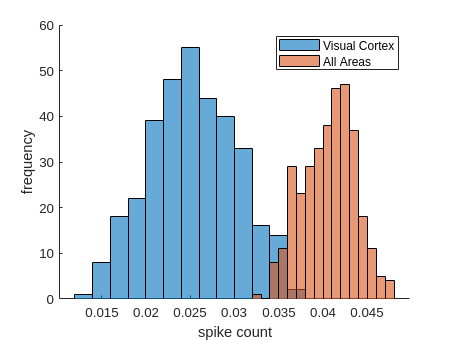

vis_cortex_data = spike_counts(:,:,brain_areas=="visual cortex");
visual_cortex_population_activity = mean(vis_cortex_data, [1,3]);
total_population_activity = mean(spike_counts, [1,3]);

clf
hold on
histogram(visual_cortex_population_activity, "DisplayName","Visual Cortex")
histogram(total_population_activity, "DisplayName","All Areas")
hold off

legend
xlabel('spike count')
ylabel('frequency')